## Domain and Method

addpath('Subroutines') % the functions are all stored in the subfolder 'Subroutines' 

We want to solve the Monge-Ampere on a rectangle $\Omega =\left(\textrm{x0},\textrm{x1}\right)\times \left(\textrm{y0},\textrm{y1}\right)$ using a monotonic wid-stencil scheme.  

x0 = -1; x1 = 1; 
y0 = -1; y1 = 1; 

padding = 0.2;
lims = [x0-padding, x1+padding, y0-padding, y1+padding]; % useful for plotting

We can choose the granularity of the mesh is controlled by the variable `N`. 

The stencil width of the difference scheme is controlled by `depth`. The figure below shows the wide stencil.

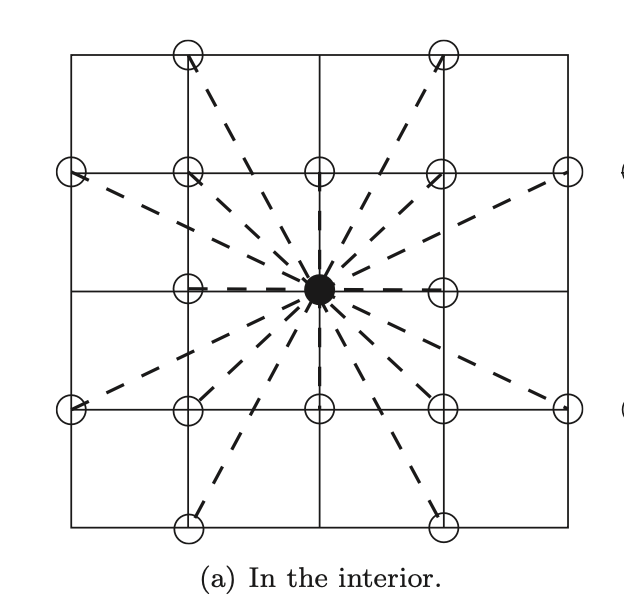

## Mesh

% Parameters needed to generate grid
N = 2^3+1; 
h = (x1-x0)/(N+1);
depth = 2; 

A special mesh must be made for the wide stencil scheme. The interior $\Omega$ and the boundary $\Gamma =\partial \Omega$ are meshed differently. The subroutine `buildMesh_Rect` creates the mesh. The subroutine returns information about the node coordinates. 

[Points,Interior,Boundary,NMatSDD,CMatSDD,theta] = buildMesh_Rect(x0,x1,y0,y1,h,depth);
% OUTPUT: 
% Points - (Np x 2) arrary of node coordinates 
% Interior - (1 x Ni) interior node indicator 
% Boundary - (Nb x 1) boundary node indicator 
% NMatSDD - (Ni x Ns*3) node adjcacency info 
% CMatSDD - (Ni x Ns*3) FD coefficient info  
% theta - (Ns x 1) angular position of stencil points 
Np = length(Points);
Ni = Interior(end);
Nb = length(Boundary);
Ns = length(theta);
fprintf('Np = %d\nNi = %d\nNb = %d\nNs = %d',Np,Ni,Nb,Ns)

Np = 193
Ni = 81
Nb = 112
Ns = 9

Let $N_p$ be the total number of points on the mesh. $N_i$ will be the number of points in the interior, $N_b$ will be the number of points on the boundary and $N_p =N_i +N_b$. 

The number of stencil points for a given point including the middle is given by $N_{\textrm{sp}}$. It depends on stencil width. For example, if `depth`=1, then $N_s =9$.  

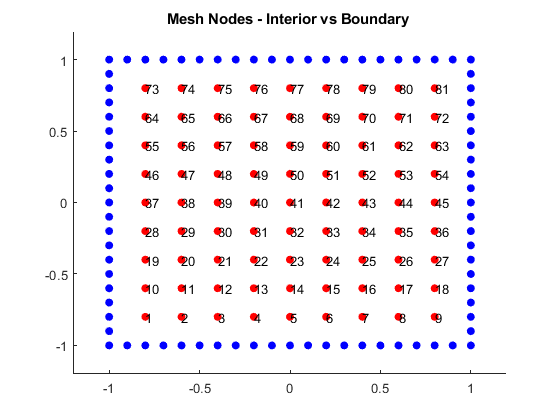

figure
hold on 
scatter(Points(Interior,1),Points(Interior,2),[],'r','filled')
scatter(Points(Boundary,1),Points(Boundary,2),[],'b','filled')
title('Mesh Nodes - Interior vs Boundary ')
xi = Points(Interior,1);
yi = Points(Interior,2);
hold on 
for i = 1:Ni 
   text(xi(i),yi(i),num2str(i))
end
axis(lims)

The plot above shows the mesh nodes. The interior nodes (marked in red) are spaced out in intervals of $h=\frac{\textrm{x1}-\textrm{x0}}{N+1}$.The interior nodes are numbered in the natural ordering. There are $N$ nodes per row. We can use this structure to determine local neighboring interior nodes.   

The boundary nodes (marked in blue) are spaced differently from the interior nodes depending on the stencil width.  

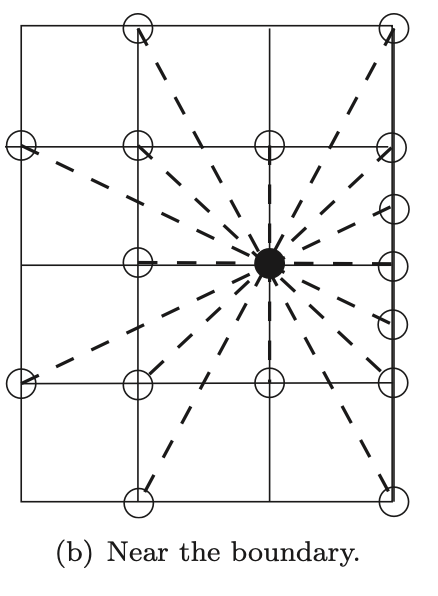

The figure above shows the wide stencil near the boundary. When near the boundary, the stencil nodes are projected onto the boundary in a way that preserves the angle. 

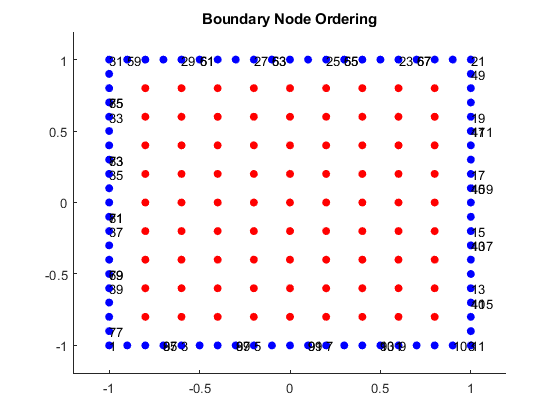

figure
hold on 
scatter(Points(Interior,1),Points(Interior,2),[],'r','filled')
scatter(Points(Boundary,1),Points(Boundary,2),[],'b','filled')
title('Boundary Node Ordering')
xi = Points(Boundary,1);
yi = Points(Boundary,2);
hold on 
for i = 1:depth:Nb
   text(xi(i),yi(i),num2str(i))
end
axis(lims)
hold off

The plot above shows how the boundary nodes are ordered. 

## NMatSSD

Every interior node has $N_s -1$ neighboring nodes which influence its derivative approximation. The information is stored in `NMatSSD`. The $i^{\mathrm{th}}$ row of the `NMatSSD` matrix corresponds to the list of neighbors of node $x_i$. 

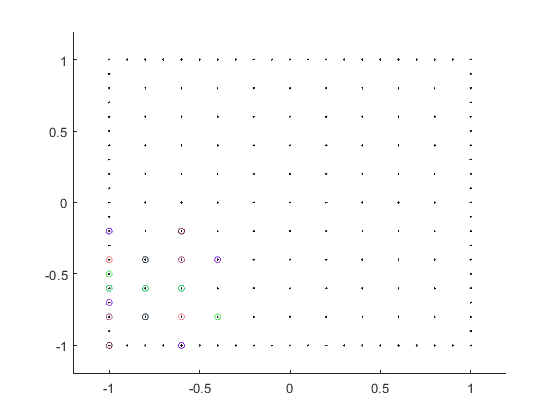

ind = N + 1; 
row = NMatSDD(ind,:); 


figure
scatter(Points(:,1),Points(:,2),1,'k')
hold on
for i = 1:Ns 
   c = rand(1,3); % random color 
   pts = Points( row((1:3)+(i-1)*3),:);
   scatter(pts(:,1),pts(:,2),20,c)
end

pts = Points(row,:);


axis(lims)

## Domain Decomposition

Let's begin with 2 subdomains. We will split the domain horizontally along the x-asix. The bottom half is $\Omega_1 =\left(\textrm{x0},\textrm{x1}\right)\times \left(\textrm{y0},0\right)$ and the top is $\Omega_2 =\left(\textrm{x0},\textrm{x1}\right)\times \left(0,\textrm{y1}\right)$.

We will create 2 subarrays of `Boundary` and `Interior `as well as an `Interface` array for the nodes on the 

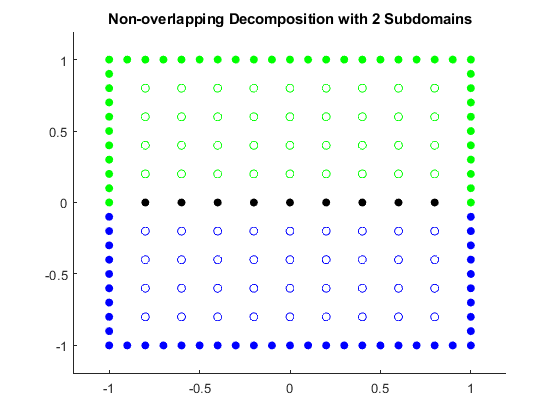

Interface = find(Points(Interior,2)==0); % points in the interior that lie on the artificial interface 
Interior1 = Interior(Points(Interior,2)<0);
Interior2 = Interior(Points(Interior,2)>0);
Boundary1 = Boundary(Points(Boundary,2)<=0);
Boundary2 = Boundary(Points(Boundary,2)>=0);

figure
hold on
c1 = [0 0 1];
c2 = [0 1 0];
scatter(Points(Interior1,1),Points(Interior1,2),[],c1)
scatter(Points(Boundary1,1),Points(Boundary1,2),[],c1,'filled')

scatter(Points(Interior2,1),Points(Interior2,2),[],c2)
scatter(Points(Boundary2,1),Points(Boundary2,2),[],c2,'filled')

scatter(Points(Interface,1),Points(Interface,2),[],[0 0 0],'filled')
axis(lims)
title('Non-overlapping Decomposition with 2 Subdomains')

The plot above shows the non-overlapping domain decomposition. The domains are color coded. The solid circles are interfaces and the open circles are interior nodes. 

## Overlapping Domains 

We want to do an overlapping domain decomposition, which means we extend our non-overlapping domains from $\Omega_i$ to $\Omega_i^*$. The overlap is controlled with a positive integer $\delta$. $\delta \;$correponds to the number of layers of nodes that each domain extends over the artificial interface. So $\delta =0$ corresponds to $\Omega_i =\Omega_i^*$ which means the overlapping region is 1 layer thick. In general the overlapping region consists of $2\delta +1$ layers of nodes.

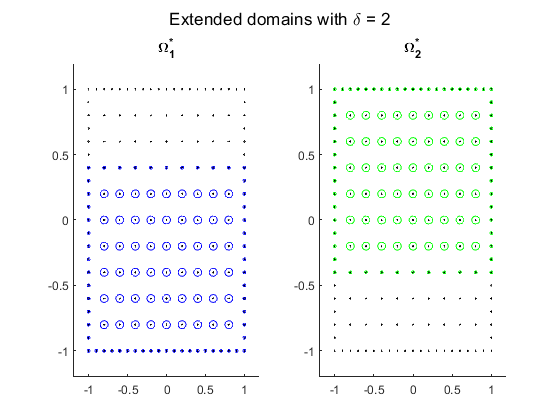

delta = 2; 
Boundary1 = Boundary(Points(Boundary,2) <= h*delta); % extend upward
Boundary2 = Boundary(Points(Boundary,2) >= -h*delta); % extend downward
Boundary1 = [Boundary1; Interface+N*delta]; % add the interface
Boundary2 = [Boundary2; Interface-N*delta]; % add the interface

for i = 1:delta
   Interior1 = [Interior1, Interface'+N*(i-1)];
   Interior2 = [Interior2, Interface'-N*(i-1)];
end



figure(4)
subplot(121)
scatter(Points(:,1),Points(:,2),1,'k')
hold on 
scatter(Points(Interior1,1),Points(Interior1,2),[],c1)
scatter(Points(Boundary1,1),Points(Boundary1,2),5,c1)
axis(lims)
title('\Omega_1^{*}')

subplot(122)
scatter(Points(:,1),Points(:,2),1,'k')
hold on 
scatter(Points(Interior2,1),Points(Interior2,2),[],c2)
scatter(Points(Boundary2,1),Points(Boundary2,2),5,c2)
hold off
axis(lims)
title('\Omega_2^{*}')
sgtitle("Extended domains with \delta = "+delta)

The plot above shows the extended domains with $\delta =2$. The number of overlapping layers of nodes is 5. 

## SSD 

## Schwarz Alternating Procedure 

order = 1;
epsilon = h^2;
% Parameters needed to solve problem

DirBC = @(x,y) (exp((x.^2+y.^2)/2));
contF = @(x,y) ((1+x.^2+y.^2).*exp(x.^2+y.^2));
F = contF(Points(Interior1,1),Points(Interior1,2));

uBdry = DirBC(Points(Boundary1,1),Points(Boundary1,2));

weight = quadWeights(theta,order);

[uSoln, perf] = quadSolver(NMatSDD,CMatSDD,F,uBdry,epsilon,weight,h);

Error using sparse
Vectors must be the same length.

Error in poissonInit (line 19)
Dvv1 = sparse(repmat(1:intLength,1,3),[NMatSDD(:,v1*3-2) NMatSDD(:,v1*3-1) NMatSDD(:,v1*3)],[CMatSDD(:,v1*3-2) CMatSDD(:,v1*3-1) CMatSDD(:,v1*3)],intLength,pLength);

Error in quadSolver (

% Solve with newton's method and no given initial guess. 

figure
% plot3(Points(:,1),Points(:,2),uSoln,'.')



order = 1;
epsilon = h^2;
% Parameters needed to solve problem

DirBC = @(x,y) (exp((x.^2+y.^2)/2));
contF = @(x,y) ((1+x.^2+y.^2).*exp(x.^2+y.^2));
% (10) Example with Radially Smooth Solution

% pos = @(x) max(x,0);
% DirBC = @(x,y) (.5*pos(((x-.5).^2+(y-.5).^2).^.5-.2).^2);
% contF = @(x,y) (pos(1-.2./sqrt((x-.5).^2+(y-.5).^2)));
% (11) Example with C1 Solution


% DirBC = @(x,y) (-sqrt(2-(x.^2+y.^2)));
% contF = @(x,y) (2*(2-(x.^2+y.^2)).^-2);
% (12) Example with blowup on Bdry



F = contF(Points(Interior,1),Points(Interior,2));
% source evaluated at the interior grid points

uBdry = DirBC(Points(Boundary,1),Points(Boundary,2));
% boundary values 

weight = quadWeights(theta,order);
% weights from angle discretization

[uSoln, perf] = quadSolver(NMatSDD,CMatSDD,F,uBdry,epsilon,weight,h);
% Solve with newton's method and no given initial guess. 

figure
plot3(Points(:,1),Points(:,2),uSoln,'.')

